# Case_A

clear all;
clc;

%-------Domain Parameter-----%
% Grid Points
global Nx; Nx = 106;
global Ny; Ny = 56;



%--Important Parameter
INFINITE = 10^12;
eta = 10^-6;
error_eta = 10^-9;
CFL = 0.5;

% To track the error for each iterations
iteration_error = [];

% Dimension of Domain
Lx = 100;
Ly = 50;

% Domain
x_plot = linspace(0, Lx, Nx-6);
y_plot = linspace(0, Ly, Ny-6);
[X_plot, Y_plot] = meshgrid(x_plot, y_plot);
% Initialize plotting coordinates for the full computational grid
x = linspace(0, Lx, Nx);
y = linspace(0, Ly, Ny);
[X, Y] = meshgrid(x, y);

% Defining velocity
global speed discomfort cost x_velocity y_velocity;

% Space Interval
global h;
h = Lx/(Nx-6);

% Total Time
t_total = 450;

% --- Obstacle modeling ----%
global obstacle;
global P1 P2 P3 P4;
global door_length;
obstacle = false(Ny,Nx);

% Create the geometry
door_length = 10;
makeGeometry(door_length);

%-------Initial Condition------% 
% Zero Density initial condition
rho_zeros = zeros(Ny,Nx);
rho = rho_zeros;

%--Function to compute Velocity using Density
function speed = makeSpeed(rho)
    global Nx Ny;
    speed = zeros(Ny,Nx);
    for i = 1:1:Nx
        for j = 1:1:Ny
            speed(j,i) = 2*(1 - rho(j,i)/10);
        end
    end
end

%--Function to compute Discomfort using Density
function discomfort = makeDiscomfort(rho)
    global Nx Ny;
    discomfort = zeros(Ny,Nx);
    for i = 1:1:Nx
        for j = 1:1:Ny
            discomfort(j,i) = 0.002*rho(j,i)*rho(j,i);
        end
    end
end

%--Function to compute Cost function using Speed and Discomfort
function cost = makeCost(speed,discomfort)
    global Nx Ny;
    cost = zeros(Ny,Nx);
    for i = 1:1:Nx
        for j = 1:1:Ny
            cost(j,i) = 1/speed(j,i) + discomfort(j,i);
        end
    end
end

speed = makeSpeed(rho);
discomfort = makeDiscomfort(rho);
cost = makeCost(speed,discomfort);

% Plotting Speed
figure(1)
contourf(X,Y,speed,'LineStyle', 'none');

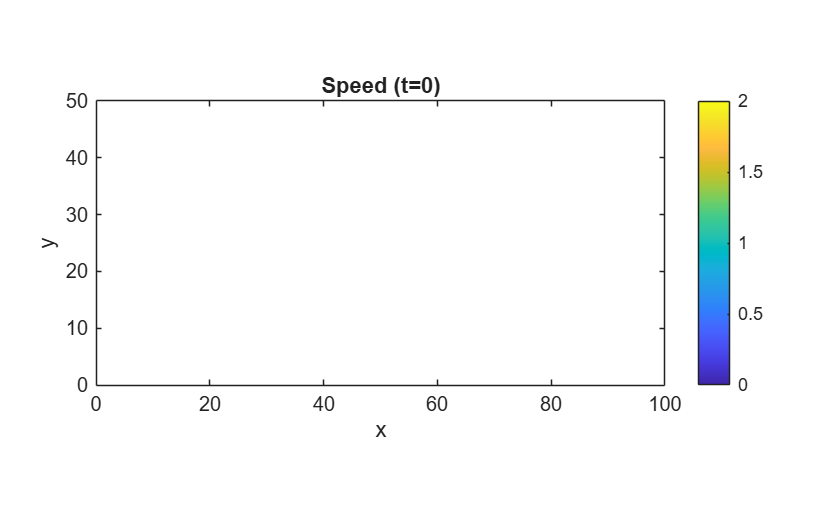

title('Speed (t=0)');
clim([0,2]);
axis equal tight;
colorbar;
xlabel('x'); ylabel('y');

% Plotting Discomfort
figure(2)
contourf(X,Y,discomfort,'LineStyle', 'none');

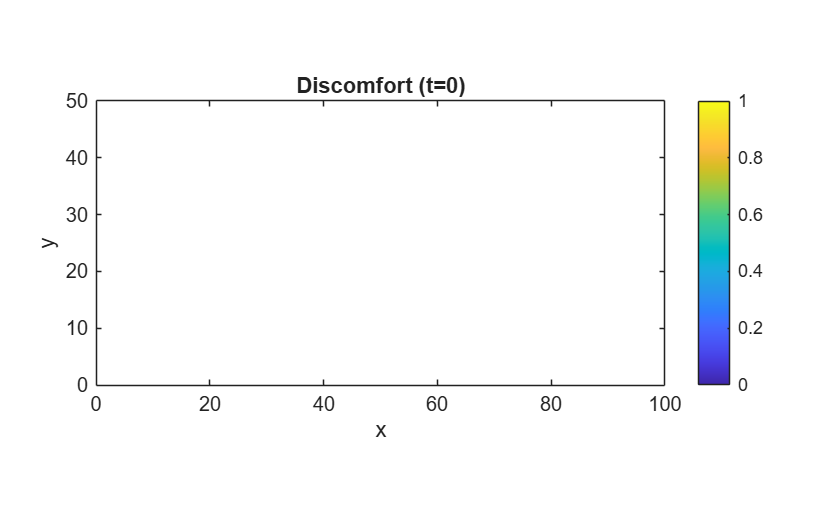

title('Discomfort (t=0)');
axis equal tight;
colorbar;
xlabel('x'); ylabel('y');

% Plotting Cost Function
figure(3);
contourf(X,Y,cost,'LineStyle', 'none');

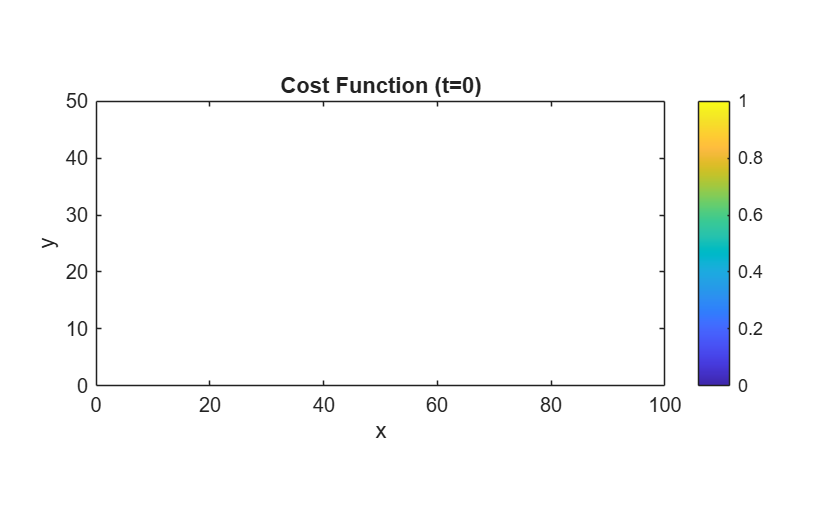

title('Cost Function (t=0)');
axis equal tight;
colorbar;
xlabel('x'); ylabel('y');

% Plotting the Initial Condition
figure(4);
contourf(X,Y,rho,'LineStyle', 'none');

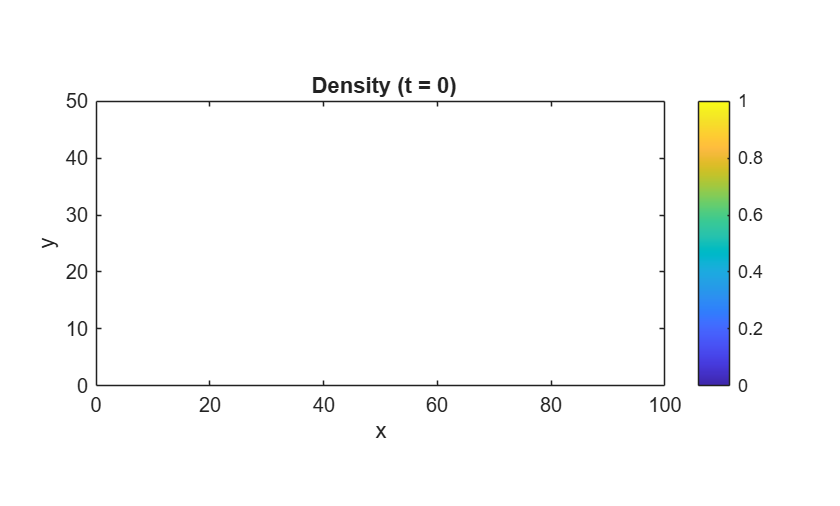

title(' Density (t = 0)');
clim([0,1]);
axis equal tight;
colorbar;
xlabel('x'); ylabel('y');

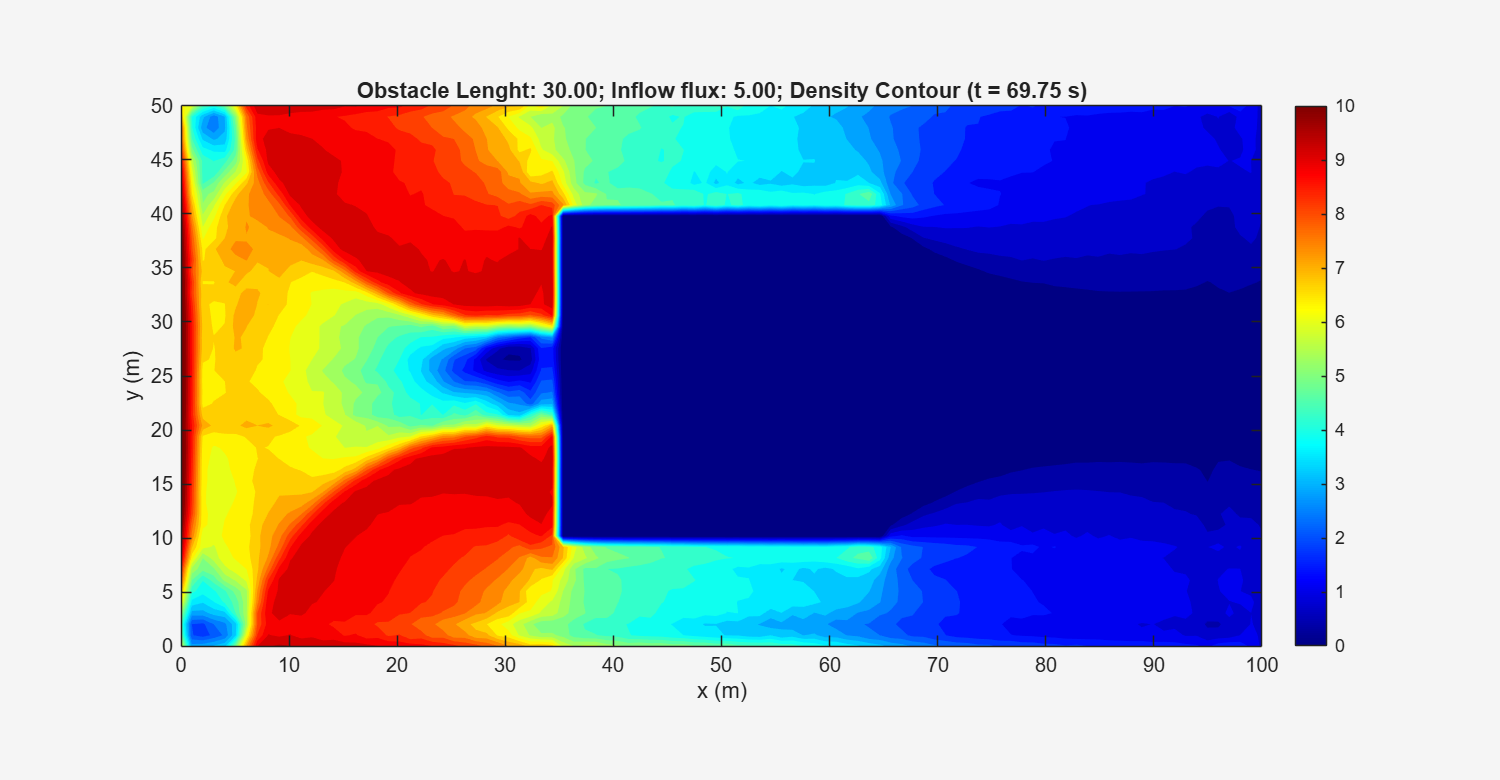

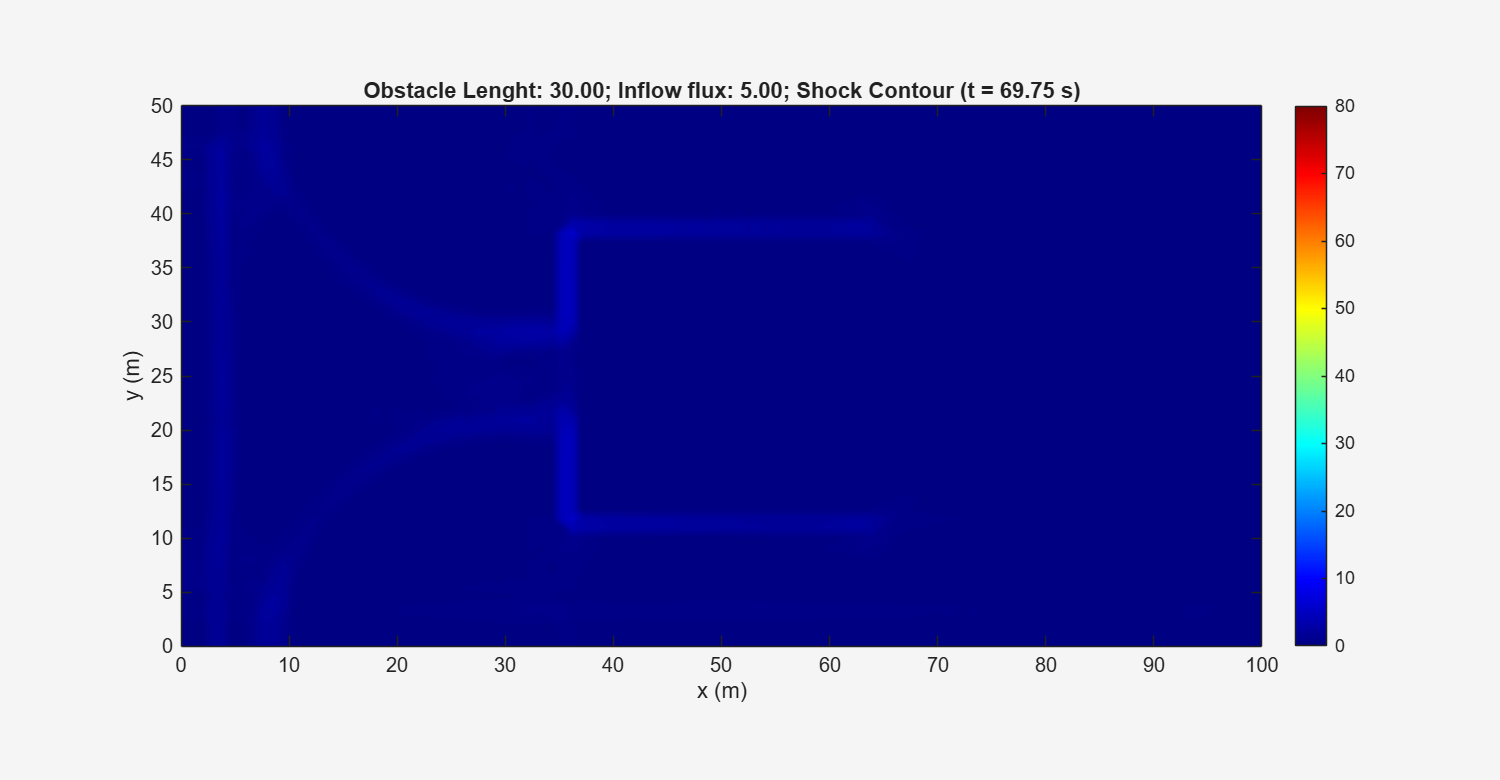

% Function that will calculate the flux depending on the u,v and Density.
% X_velocity and y_velocity will be found using the potential.
function flux = makeFlux(rho,x_velocity,y_velocity)
    global Nx Ny;

    % Initializing Flux
    flux_x = zeros(Ny,Nx);
    flux_y = zeros(Ny,Nx);
    flux = zeros(2, Ny, Nx);

    for i = 1:1:Nx
        for j = 1:1:Ny
            
            flux_x(j,i) = rho(j,i) * x_velocity(j,i);
            flux_y(j,i) = rho(j,i) * y_velocity(j,i);

            flux(1,j,i) = flux_x(j,i);
            flux(2,j,i) = flux_y(j,i);
        end
    end 
end

function flow_rate = Capture_Flow_Rate(rho, station)
    global x_velocity Ny P2 P4 h;
    flow_rate = 0;
    switch station
        case 'A'
            for j = 4:P2
                flow_rate = flow_rate + (rho(j,54) * x_velocity(j,54) * h);
            end
        case 'B'
            for j = P4:Ny-3
                flow_rate = flow_rate + (rho(j,54) * x_velocity(j,54) * h);
            end
    end
end

% This boolean value will be used to capture the densities.
capture_flux = true;

% This will be used for plotting
x_plot = linspace(0, Lx, Nx-6);
y_plot = linspace(0, Ly, Ny-6);
% Stopping condition
stop_low = -1;
stop_high = 11;

% Video Capturing
rho_max = 10;   % z-axis cap for the surface (matches clim([0 10]) used in the contour)
vel_max = 2;
shock_max = 80; % This is derived for using in clim

global inflow_flux;

% This loop is for the Length of the obstacle
for length = 30:10:30
    door_length = length;
    makeGeometry(door_length);

    % Prepare output directory for the current obstacle length
    outputDirectory = sprintf('L_%d', length);
    if ~exist(outputDirectory, 'dir')
        mkdir(outputDirectory);
    end

    for flux = 4.0:0.5:5.0
        inflow_flux = flux;

        % the corner and store it in the array corner_density and simulation_time.
        simulation_time = [];
        Flow_rate_A = [];
        Flow_rate_B = [];

        xVelocityHistory = [];
        yVelocityHistory = [];

        % Setting the Density
        rho = rho_zeros;

        %--Pre allocating the memory
        rho_n = zeros(Ny,Nx);
        rho_1 = zeros(Ny,Nx);
        rho_2 = zeros(Ny,Nx);
        rho_next = zeros(Ny,Nx);

        %-----------MAIN SOLVER------------%
        t = 0; 
        step = 0; % For plotting at regular interval

        % ---- PREPARE THE VIDEOS AND FILES ---- %
        % Density Contour
        figContour = figure('Visible','off','Position',[100 100 1000 520]);
        axContour = axes(figContour);
        colormap(axContour,'jet');
        colorbar(axContour);
        vContour = VideoWriter(fullfile(outputDirectory, sprintf('Density_Contour_L_%0.2f_F_%0.2f.mp4', length, flux)), 'MPEG-4');
        vContour.FrameRate = 30;
        open(vContour);

        % Shock Visualization
        figShock = figure('Visible','off','Position',[100 100 1000 520]);
        axShock = axes(figShock);
        colormap(axShock,'jet');
        colorbar(axShock);
        vShock = VideoWriter(fullfile(outputDirectory, sprintf('Shock_Contour_L_%0.2f_F_%0.2f.mp4',length, flux)), 'MPEG-4');
        vShock.FrameRate = 30;
        open(vShock);
        
        while t < t_total

    
            % Computing Cost For the density rho
            speed = makeSpeed(rho);
            discomfort = makeDiscomfort(rho);
            cost = makeCost(speed,discomfort);
    
            %-- Calculate Initial Phi guess using Lower order Fast Sweep
            phi_first_order = First_order_Godunov_Fast_Sweep_Algorithm(cost,h,INFINITE);
            %-- Calculate The final phi using higher order scheme and above initial guess 
            phi = weno_fastsweep(cost,h,eta,error_eta,INFINITE,phi_first_order,iteration_error);
    
            % Extrapolation of the phi values
            % Bottom Edge   (3 Ghost Points)
            phi(3,:) = phi(4,:); 
            phi(2,:) = phi(3,:); 
            phi(1,:) = phi(2,:);  
            % Top Edge      (3 Ghost Points)
            phi(Ny-2,:) = phi(Ny-3,:);
            phi(Ny-1,:) = phi(Ny-2,:); 
            phi(Ny,:) = phi(Ny-1,:);             
            % Right Edge (3 Ghost Points)
            for j = 1:Ny
                if (j >= 9 && j <= 23) || (j >= 34 && j <= 48)   % exit rows: linear extrapolation
                    slope = phi(j,Nx-3) - phi(j,Nx-4);
                    phi(j,Nx-2) = phi(j,Nx-3) + slope;
                    slope = phi(j,Nx-4) - phi(j,Nx-5);
                    phi(j,Nx-1) = phi(j,Nx-2) + slope;
                    slope = phi(j,Nx-5) - phi(j,Nx-6);
                    phi(j,Nx)   = phi(j,Nx-1) + slope;
                else                                               % wall rows: keep flat copy
                    phi(j,Nx-2) = phi(j,Nx-3);
                    phi(j,Nx-1) = phi(j,Nx-2);
                    phi(j,Nx)   = phi(j,Nx-1);
                end
            end             
            % Left Edge     (3 Ghost Points)
            phi(:,3) = phi(:,4); 
            phi(:,2) = phi(:,3); 
            phi(:,1) = phi(:,2);  
    
            %--Calculate the Components of Velocity
            [phi_x, phi_y] = gradient(phi, h, h); % partial derivatives of phi in x and y
            mag_phi = sqrt(phi_x.^2 + phi_y.^2);
            mag_phi = max(mag_phi, eta);          % To be safe with denominator
    
            for i = 1:1:Nx
                for j = 1:1:Ny
                    x_velocity(j,i) = speed(j,i) * (- phi_x(j,i))/mag_phi(j,i);
                    y_velocity(j,i) = speed(j,i) * (- phi_y(j,i))/mag_phi(j,i);
                end
            end
    
            % Updating the delta_t with proper CFL condition (Stochastic paper)
            u_max = max(abs(x_velocity(:)));
            v_max = max(abs(y_velocity(:)));
            %dt = CFL / ( ( u_max/h ).^(5/3) + ( v_max/h ).^(5/3) + 1e-12 );
            dt = CFL * h / ( ( u_max ) + ( v_max ) + 1e-12 );
    
            % -- Making rho_n and RHS of rho_n
            rho_n = rho;
    
            semi_discritze_form_rho_n = makeRHS(rho_n,t,speed);
    
            % -- Extrapolation (My Intuition)
            % Left Edge     (3 Ghost Points)
            rho_n(:,3) = rho_n(:,4); 
            rho_n(:,2) = rho_n(:,3); 
            rho_n(:,1) = rho_n(:,2);
            % Bottom Edge   (3 Ghost Points)
            rho_n(3,:) = rho_n(4,:); 
            rho_n(2,:) = rho_n(3,:); 
            rho_n(1,:) = rho_n(2,:); 
            % Top Edge      (3 Ghost Points)
            rho_n(Ny-2,:) = rho_n(Ny-3,:); 
            rho_n(Ny-1,:) = rho_n(Ny-2,:); 
            rho_n(Ny,:) = rho_n(Ny-1,:);
            % Right Edge    (3 Ghost Points)
            rho_n(:,Nx-2) = rho_n(:,Nx-3);
            rho_n(:,Nx-1) = rho_n(:,Nx-2); 
            rho_n(:,Nx) = rho_n(:,Nx-1);
    
            % Check for the negative rho_n values
            if any(rho_n(:) < stop_low) || any(rho_n(:) > stop_high)
                break;
            end
    
            % ---------- Making the RHO_1 and then RHS of rho_1 ------ %
            for i = 4:1:Nx-3
                for j = 4:1:Ny-3
                    if(~obstacle(j,i))
                        rho_1(j,i) = rho_n(j,i) + dt * semi_discritze_form_rho_n(j-3,i-3);
                    else
                        rho_1(j,i) = 0;
                    end
                end
            end
    
            % -- Extrapolation (My Intuition)
            % Left Edge     (3 Ghost Points)
            rho_1(:,3) = rho_1(:,4); 
            rho_1(:,2) = rho_1(:,3); 
            rho_1(:,1) = rho_1(:,2);
            % Bottom Edge   (3 Ghost Points)
            rho_1(3,:) = rho_1(4,:); 
            rho_1(2,:) = rho_1(3,:); 
            rho_1(1,:) = rho_1(2,:); 
            % Top Edge      (3 Ghost Points)
            rho_1(Ny-2,:) = rho_1(Ny-3,:); 
            rho_1(Ny-1,:) = rho_1(Ny-2,:); 
            rho_1(Ny,:) = rho_1(Ny-1,:);
            % Right Edge    (3 Ghost Points)
            rho_1(:,Nx-2) = rho_1(:,Nx-3);
            rho_1(:,Nx-1) = rho_1(:,Nx-2); 
            rho_1(:,Nx) = rho_1(:,Nx-1);              
    
            % -- RHS of discretized form using rho_1
            semi_discritze_form_rho_1 = makeRHS(rho_1,t,speed);
    
            % Check for the negative rho_1 values
            if any(rho_1(:) < stop_low) || any(rho_1(:) > stop_high)
                break;
            end
    
            %--------- Making the RHO_2 and RHS of RHO_2 ----------%
            for i = 4:1:Nx-3
                for j = 4:1:Ny-3
                    if(~obstacle(j,i))
                        rho_2(j,i) = 3/4 * rho_n(j,i) + 1/4 * (rho_1(j,i) + dt * semi_discritze_form_rho_1(j-3,i-3));
                    else
                        rho_2(j,i) = 0;
                    end
    
                end
            end
    
            % -- Extrapolation (My Intuition)
            % Left Edge     (3 Ghost Points)
            rho_2(:,3) = rho_2(:,4); 
            rho_2(:,2) = rho_2(:,3); 
            rho_2(:,1) = rho_2(:,2);  
            % Bottom Edge   (3 Ghost Points)
            rho_2(3,:) = rho_2(4,:); 
            rho_2(2,:) = rho_2(3,:); 
            rho_2(1,:) = rho_2(2,:);  
            % Top Edge      (3 Ghost Points)
            rho_2(Ny-2,:) = rho_2(Ny-3,:); 
            rho_2(Ny-1,:) = rho_2(Ny-2,:); 
            rho_2(Ny,:) = rho_2(Ny-1,:);
            % Right Edge    (3 Ghost Points)
            rho_2(:,Nx-2) = rho_2(:,Nx-3);
            rho_2(:,Nx-1) = rho_2(:,Nx-2); 
            rho_2(:,Nx) = rho_2(:,Nx-1);                 
    
            % -- RHS of discretized form using rho_2
            semi_discritze_form_rho_2 = makeRHS(rho_2,t,speed);
    
            % Check for the negative rho_2 values
            if any(rho_2(:) < stop_low) || any(rho_2(:) > stop_high)
                break;
            end
    
            %----------Making the rho_next-------------------------%
    
            for i = 4:1:Nx-3
                for j = 4:1:Ny-3
                    if(~obstacle(j,i))
                        rho_next(j,i) = 1/3 * rho_n(j,i) + 2/3 * (rho_2(j,i) + dt * semi_discritze_form_rho_2(j-3,i-3));
                    else
                        rho_next(j,i) = 0;
                    end
                end
            end  
    
            % -- Extrapolation (My Intuition)
            % Left Edge     (3 Ghost Points)
            rho_next(:,3) = rho_next(:,4); 
            rho_next(:,2) = rho_next(:,3); 
            rho_next(:,1) = rho_next(:,2);    
            % Bottom Edge   (3 Ghost Points)
            rho_next(3,:) = rho_next(4,:); 
            rho_next(2,:) = rho_next(3,:); 
            rho_next(1,:) = rho_next(2,:);    
            % Top Edge      (3 Ghost Points)
            rho_next(Ny-2,:) = rho_next(Ny-3,:); 
            rho_next(Ny-1,:) = rho_next(Ny-2,:); 
            rho_next(Ny,:) = rho_next(Ny-1,:);
            % Right Edge    (3 Ghost Points)
            rho_next(:,Nx-2) = rho_next(:,Nx-3); 
            rho_next(:,Nx-1) = rho_next(:,Nx-2); 
            rho_next(:,Nx) = rho_next(:,Nx-1);
    
            %--Check if any of the density values is equal to zero
            if any(rho_next(:) < stop_low) || any(rho_next(:) > stop_high)
                break;
            end
    
            % Substituting back the rho value
            rho = rho_next;

            
    
            % Calculate the Shocks
            [gradX, gradY] = gradient(rho, h, h);
            shockWave = sqrt(gradX.^2 + gradY.^2);
            % Calculate Velocity unit vector for Crowd A
            velocityUnit = [x_velocity(:), y_velocity(:)];
            velocityMagnitude = sqrt(sum(velocityUnit.^2, 2));
            velocityUnit = velocityUnit ./ max(velocityMagnitude, 1e-12); % 
            % Avoid division by zero
            % Calculate the vector dot product
            dotProduct = gradX(:) .* velocityUnit(:,1) + gradY(:) .* velocityUnit(:,2);
            
            % Calculate the outflow rate at station A and B
            Flow_rate_A(end+1) = Capture_Flow_Rate(rho,'A');
            Flow_rate_B(end+1) = Capture_Flow_Rate(rho,'B');
            
            % Save velocity profiles for this time step
            xVelocityHistory(end+1, :) = x_velocity(4:Ny-3, 94).';
            yVelocityHistory(end+1, :) = y_velocity(4:Ny-3, 94).';
            
            
    
            %--Plotting the rho_next;
            if mod(step, 2) == 0

                % ---- Plot Density Contour ----
                figure(figContour);
                cla(axContour);
                contourf(axContour, X_plot, Y_plot, rho(4:Ny-3, 4:Nx-3), 30, 'LineColor', 'none');
                colormap(axContour, jet);
                clim(axContour, [0 rho_max]);
                title(axContour, sprintf('Obstacle Lenght: %0.2f; Inflow flux: %0.2f; Density Contour (t = %.2f s)',length, flux, t));
                xlabel(axContour, 'x (m)');
                ylabel(axContour, 'y (m)');
                axis(axContour, 'equal');
                colorbar(axContour);
                frame = getframe(figContour);
                writeVideo(vContour, frame);
                
                
                % ---- Plot Shock Contour ----
                figure(figShock);
                cla(axShock);
                [gradX, gradY] = gradient(rho, h, h);
                shockWave = sqrt(gradX.^2 + gradY.^2);
                contourf(axShock, X, Y, shockWave, 30, 'LineColor', 'none');
                colormap(axShock, jet);
                clim(axShock, [0 shock_max]);
                title(axShock, sprintf('Obstacle Lenght: %0.2f; Inflow flux: %0.2f; Shock Contour (t = %.2f s)',length, flux, t));
                xlabel(axShock, 'x (m)');
                ylabel(axShock, 'y (m)');
                axis(axShock, 'equal');
                colorbar(axShock);
                frame = getframe(figShock);
                writeVideo(vShock, frame);
    
            end
    
            % Updating the time
            t = t + dt;
            simulation_time(end+1) = t;
    
            step = step + 1;
        end

        % Close the videos that are generated
        % Finalize video output for the current simulation
        close(vContour);
        close(vShock);

        % Save the file of the Outflow flux at A and B and Velocity at C
        file_name = sprintf("Outflow_A_L_%0.2f_F_%0.2f.csv",length,flux);
        data = [Flow_rate_A(:), simulation_time(:)];
        writematrix(data,file_name);

        file_name = sprintf("Outflow_B_L_%0.2f_F_%0.2f.csv",length,flux);
        data = [Flow_rate_B(:), simulation_time(:)];
        writematrix(data,file_name);

        % Capture the X Velocity with time
        file_name = sprintf("X_Velocity_at_C_L_%0.2f_F_%0.2f.csv",length,flux);
        data = [simulation_time(:),xVelocityHistory];
        writematrix(data,file_name);

        % Capture the Y Velocity with time
        file_name = sprintf("Y_Velocity_at_C_L_%0.2f_F_%0.2f.csv",length,flux);
        data = [simulation_time(:),yVelocityHistory];
        writematrix(data,file_name);
        
    end
end



% This function will assign the P's that will be used to make the obstacle and apply boundary condition on it.
function makeGeometry(obstacle_length)
    global P1 P2 P3 P4 obstacle
    obstacle(:) = false;
    switch obstacle_length
        case 10
            P1 = 49; P2 = 24; P3 = 58; P4 = 33;
        case 20
            P1 = 44; P2 = 19; P3 = 63; P4 = 38;
        case 30
            P1 = 39; P2 = 14; P3 = 68; P4 = 43;
        case 40
            P1 = 34; P2 = 9; P3 = 73; P4 = 48;
    end
    % Assign the obstacle
    obstacle(P2:P4, P1:P3) = true;
end

## First order Godunov Fast Sweep Algorithm (Older Version)

function phi = First_order_Godunov_Fast_Sweep_Algorithm(c,h,INFINITE)
    global Nx Ny obstacle;
    phi = INFINITE*ones(Ny, Nx);    % Initial potential field

    % Exit Boundary (Right boundary at the exit)
    for j = 1 : Ny
        phi(j,Nx-3) = 0;
    end

    %---------------------------------------------
    % Fast Sweeping Iterations
    %---------------------------------------------
    for sweep = 1:20

        % Sweep 1:
        for i = 4:Nx-2
            for j = 4:Ny-2
                if ~obstacle(j, i)
                    phi = update_phi(phi, c, i, j, h);
                    if i == Nx-3 && ((j >= 9 && j <= 23) || (j >= 34 && j <= 48))
                        phi(j,i) = 0;
                    end
                else
                    phi(j,i) = INFINITE;
                end
            end
        end

        % Sweep 2:
        for i = Nx-1:-1:2
            for j = 2:Ny-1
                if ~obstacle(j, i)
                    phi = update_phi(phi, c, i, j, h);
                    if i == Nx-3 && ((j >= 9 && j <= 23) || (j >= 34 && j <= 48))
                        phi(j,i) = 0;
                    end
                else
                    phi(j,i) = INFINITE;
                end
            end
        end

        % Sweep 3: 
        for i = Nx-1:-1:2
            for j = Ny-1:-1:2
                if ~obstacle(j, i)
                    phi = update_phi(phi, c, i, j, h);
                    if i == Nx-3 && ((j >= 9 && j <= 23) || (j >= 34 && j <= 48))
                        phi(j,i) = 0;
                    end
                else
                    phi(j,i) = INFINITE;
                end
            end
        end

        % Sweep 4:
        for i = 2:Nx-1
            for j = Ny-1:-1:2
                if ~obstacle(j, i)
                    phi = update_phi(phi, c, i, j, h);
                    if i == Nx-3
                        phi(j,i) = 0;
                    end
                else
                    phi(j,i) = INFINITE;
                end
            end
        end
    
        % Extrapolation of the phi values

        % Bottom Edge   (3 Ghost Points)
        phi(3,:) = phi(4,:); 
        phi(2,:) = phi(3,:); 
        phi(1,:) = phi(2,:);

        % Top Edge      (3 Ghost Points)
        phi(Ny-2,:) = phi(Ny-3,:); 
        phi(Ny-1,:) = phi(Ny-2,:); 
        phi(Ny,:) = phi(Ny-1,:);

        % Right Edge    (3 Ghost Points)
        for j = 1:Ny
            slope = phi(j,Nx-3) - phi(j,Nx-4);
            phi(j,Nx-2) = phi(j,Nx-3) + slope;
            slope = phi(j,Nx-4) - phi(j,Nx-5);
            phi(j,Nx-1) = phi(j,Nx-2) + slope;
            slope = phi(j,Nx-5) - phi(j,Nx-6);
            phi(j,Nx)   = phi(j,Nx-1) + slope;
        end

        % Left Edge     (3 Ghost Points)
        phi(:,3) = phi(:,4); 
        phi(:,2) = phi(:,3); 
        phi(:,1) = phi(:,2);  
    end
end

% Subfunction: Update one grid point using Godunov scheme

function phi = update_phi(phi, c, i, j, dx)
    a = min(phi(j, i-1), phi(j, i+1)); % x-direction neighbors
    b = min(phi(j-1, i), phi(j+1, i)); % y-direction neighbors
    c_i = c(j, i); % Local inverse speed
    if abs(a - b) >= c_i * dx
        phi(j, i) = min(a, b) + c_i * dx;
        else
            inside = 2 * (c_i * dx)^2 - (a - b)^2;
        if inside >= 0
            phi(j, i) = (a + b + sqrt(inside)) / 2;
        end
    end
end


## WENO FAST SWEEP

function phi = weno_fastsweep(c,h,eta,error_eta,INFINITE,initial_guess,iteration_error)

    global Nx Ny obstacle;

    % Phi is initialized with infinity
    phi = initial_guess;
    phi_old = INFINITE * ones(size(phi));

    % Iterations
    iterations = 0;
    loop_safety = 0;

    % Iterations
    while (sum(abs(phi(:)-phi_old(:))) > error_eta && loop_safety<1000)

        %fprintf("Iteration = %d ",iterations);
        err = sum(abs(phi(:)-phi_old(:)));
        %fprintf("Error = %0.10f\n",err);

        phi_old = phi;
        iterations = iterations + 1;
        iteration_error(iterations) = err;
        loop_safety = loop_safety + 1;

        for sweep = 1:4
            switch sweep
                case 1 
                    ix = 4:1:Nx-3; jy = 4:1:Ny-3;
                case 2 
                    ix = 4:1:Nx-3; jy = Ny-3:-1:4;
                case 3 
                    ix = Nx-3:-1:4; jy = 4:1:Ny-3;
                case 4 
                    ix = Nx-3:-1:4; jy = Ny-3:-1:4;
            end 

            for i = ix
                for j = jy
                    %if the point is outside the obstacle
                    if(~obstacle(j,i))
                        %------------Calculating the phix_min---------_%

                        r_back = (eta + (phi(j,i) - 2*phi(j,i-1) + phi(j,i-2))^2)/(eta + (phi(j,i+1) - 2*phi(j,i) + phi(j,i-1))^2);
                        r_front = (eta + (phi(j,i) - 2*phi(j,i+1) + phi(j,i+2))^2)/(eta + (phi(j,i+1) - 2*phi(j,i) + phi(j,i-1))^2);
    
                        % Calculate the w
                        w_front = 1/(1+2*(r_front^2));
                        w_back = 1/(1+2*(r_back^2));
    
                        % Dell phi by Dell x plus and minus
                        phix_minus = (1-w_back)*((phi(j,i+1)-phi(j,i-1))/(2*h)) + w_back*((3*phi(j,i) - 4*phi(j,i-1) + phi(j,i-2))/(2*h));
                        phix_plus = (1-w_front)*((phi(j,i+1)-phi(j,i-1))/(2*h)) + w_front*((-3*phi(j,i)+4*phi(j,i+1)-phi(j,i+2))/(2*h));
                        
                        
                        phix_min = min((phi(j,i) - h*phix_minus),(phi(j,i) + h*phix_plus));
                        
                        %-----------calculating the phiy_min---------%

                        r_back = (eta + (phi(j,i) - 2*phi(j-1,i) + phi(j-2,i))^2) / (eta + (phi(j+1,i) - 2*phi(j,i) + phi(j-1,i))^2);
                        r_front = (eta + (phi(j,i) - 2*phi(j+1,i) + phi(j+2,i))^2) / (eta + (phi(j+1,i) - 2*phi(j,i) + phi(j-1,i))^2);
    
                        % Calculate the w
                        w_front = 1 / (1 + 2*(r_front^2));
                        w_back = 1 / (1 + 2*(r_back^2));
    
                        % Dell phi by Dell x plus and minus
                        phiy_minus = (1-w_back) * ((phi(j+1,i)-phi(j-1,i))/(2*h)) + w_back * ((3*phi(j,i) - 4*phi(j-1,i) + phi(j-2,i))/(2*h));
                        phiy_plus = (1-w_front) * ((phi(j+1,i) - phi(j-1,i))/(2*h)) + w_front * ((-3*phi(j,i) + 4*phi(j+1,i) - phi(j+2,i))/(2*h));
                        
                        
                        phiy_min = min((phi(j,i) - h*phiy_minus), (phi(j,i) + h*phiy_plus));

                        if abs(phix_min - phiy_min) >= c(j,i)*h
                            phi(j,i) = min(phiy_min,phix_min) + c(j,i)*h;
                        else
                            phi(j,i) = ((phix_min + phiy_min) + (2*(c(j,i)*h)^2 - (phix_min - phiy_min)^2)^0.5)/2;
                        end

                        % Enforce the value of phi to be zero at the right boundary
                        if(i == Nx-3)
                            phi(j,i) = 0;
                        end

                    % If the point is inside the obstacle
                    else 
                        phi(j,i) = INFINITE;
                    end 
                end
            end
        end   
    end
end


## RHS of Semi Discretize Form

function semi_discrite_form =  makeRHS(rho,t,speed)
    global Nx Ny x_velocity y_velocity h obstacle inflow_flux P1 P2 P3 P4;
    semi_discrite_form = zeros(Ny-6,Nx-6);

    %--Flux for the given rho distribution
    flux = makeFlux(rho,x_velocity,y_velocity);
    flux_x = squeeze(flux(1,:,:));
    flux_y = squeeze(flux(2,:,:));

    % Calculating the maximum speed (multiplying by 1.5 as suggested)
    alpha_x = max(abs(x_velocity(:))) * 1.5;
    alpha_y = max(abs(y_velocity(:))) * 1.5;


    % -- Calculating the value of f+ and f- at {i+2,i+1,i,i-1,i-2,i-3} -- %
    fx_negative_whole = zeros(Ny,Nx);
    fx_positive_whole = zeros(Ny,Nx);
    fy_negative_whole = zeros(Ny,Nx);
    fy_positive_whole = zeros(Ny,Nx);

    for j = 1:1:Ny
        for i=1:1:Nx
            fx_positive_whole(j,i) = 1/2 * (flux_x(j,i) + alpha_x*rho(j,i));
            fx_negative_whole(j,i) = 1/2 * (flux_x(j,i) - alpha_x*rho(j,i));
            fy_positive_whole(j,i) = 1/2 * (flux_y(j,i) + alpha_y*rho(j,i));
            fy_negative_whole(j,i) = 1/2 * (flux_y(j,i) - alpha_y*rho(j,i));
        end
    end
    
    % -- Computing the RHS of Semi Discrete form.
    for i = 4:1:Nx-3
        for j = 4:1:Ny-3
            % compute only at the points where obstacle doesn't exist
            if(~obstacle(j,i))
                %--X--%
    
                % fx{+}_[i+1/2,j] - Given in the paper
                fx_plus_x_half_forward = stencil( ...
                    fx_positive_whole(j,i-2), ...
                    fx_positive_whole(j,i-1), ...
                    fx_positive_whole(j,i), ...
                    fx_positive_whole(j,i+1), ...
                    fx_positive_whole(j,i+2));
                
                % fx{+}_[i-1/2,j] - By substituting i -> (i-1) in fx{+}_[i+1/2,j]
                fx_plus_x_half_backward = stencil( ...
                    fx_positive_whole(j,i-3), ...
                    fx_positive_whole(j,i-2), ...
                    fx_positive_whole(j,i-1), ...
                    fx_positive_whole(j,i), ...
                    fx_positive_whole(j,i+1));
    
                % fx{-}_[i+1/2,j] ( mirror of fx{+}_[i+1/2,j] )
                fx_minus_x_half_forward = stencil( ...
                    fx_negative_whole(j,i+3), ...
                    fx_negative_whole(j,i+2), ...
                    fx_negative_whole(j,i+1), ...
                    fx_negative_whole(j,i), ...
                    fx_negative_whole(j,i-1));
                
                % fx{-}_[i-1/2,j] ( mirror of fx{+}_[i-1/2,j] )
                fx_minus_x_half_backward = stencil( ...
                    fx_negative_whole(j,i+2), ...
                    fx_negative_whole(j,i+1), ...
                    fx_negative_whole(j,i), ...
                    fx_negative_whole(j,i-1), ...
                    fx_negative_whole(j,i-2));
    
                %--Y--%
    
                % fy{+}_[i,j+1/2]
                fy_plus_y_half_forward = stencil( ...
                    fy_positive_whole(j-2,i), ...
                    fy_positive_whole(j-1,i), ...
                    fy_positive_whole(j,i), ...
                    fy_positive_whole(j+1,i), ...
                    fy_positive_whole(j+2,i));
                
                % fy{+}_[i,j-1/2]
                fy_plus_y_half_backward = stencil( ...
                    fy_positive_whole(j-3,i), ...
                    fy_positive_whole(j-2,i), ...
                    fy_positive_whole(j-1,i), ...
                    fy_positive_whole(j,i), ...
                    fy_positive_whole(j+1,i));
    
                % fy{-}_[i,j+1/2]
                fy_minus_y_half_forward = stencil( ...
                    fy_negative_whole(j+3,i), ...
                    fy_negative_whole(j+2,i), ...
                    fy_negative_whole(j+1,i), ...
                    fy_negative_whole(j,i), ...
                    fy_negative_whole(j-1,i));
                
                % fy{-}_[i,j-1/2]
                fy_minus_y_half_backward = stencil( ...
                    fy_negative_whole(j+2,i), ...
                    fy_negative_whole(j+1,i), ...
                    fy_negative_whole(j,i), ...
                    fy_negative_whole(j-1,i), ...
                    fy_negative_whole(j-2,i));
                
                fx_positive_half = fx_plus_x_half_forward + fx_minus_x_half_forward;
                fx_negative_half = fx_plus_x_half_backward + fx_minus_x_half_backward;
                fy_positive_half = fy_plus_y_half_forward + fy_minus_y_half_forward;
                fy_negative_half = fy_plus_y_half_backward + fy_minus_y_half_backward;
    
    
                %--Boundary Condition -- %
    
                % Left Boundary (Flux need not be computed)
                if(i == 4)
                    % Y flux is said to be zero at the inflow
                    fy_negative_half = 0;
                    fx_negative_half = inflow_flux;
                end
    
                % Bottom Wall (Normal Flux on the boundary is zero)
                if(j == 4)
                    fy_negative_half = 0;
                end
                % Top Wall (Normal Flux on the boundary is zero)
                if(j == Ny-3)
                    fy_positive_half = 0;
                end
                % Right Boundary (Normal Flux at non-exit is zero)
                if(i == Nx-3)
                    fx_positive_half = flux_x(j, Nx-3);
                    fy_positive_half = flux_y(j, Nx-3);
                end

                % At the Boundary of the obstacle
                if(j >= P2 && j <= P4)
                    if(i == P1-1)
                        fx_positive_half = 0; % Left Boundary
                    elseif(i == P3+1)
                        fx_negative_half = 0; % Right Boundary
                    end
                elseif(i >= P1 && i <= P3)
                    if(j == P2-1)
                        fy_positive_half = 0; % Bottom Boundary
                    elseif(j == P4+1)
                        fy_negative_half = 0; % Top Boundary
                    end
                end


                % Computing RHS of Semi Discretized form
                semi_discrite_form(j-3,i-3) = - 1/h * (fx_positive_half - fx_negative_half) - 1/h * (fy_positive_half - fy_negative_half);
            
            else
                % Else when there is an obstacle
            end    
        end
    end
end

## WENO Advection Stencil

% To compute f half. Order of input matters
function f = stencil(f1,f2,f3,f4,f5)

    eta = 10^-6;

    % Compute S values
    s_1 = ((1/3) * f1) + ((-7/6) * f2) + ((11/6) * f3);
    s_2 = ((-1/6) * f2) + ((5/6) * f3) + ((1/3) * f4);
    s_3 = ((1/3) * f3) + ((5/6) * f4) + ((-1/6) * f5);

    % Compute Beta
    beta_1 = 13/12 * (f1 - 2*f2 + f3)^2 + 1/4 * (f1 - 4*f2 + 3*f3)^2;
    beta_2 = 13/12 * (f2 - 2*f3 + f4)^2 + 1/4 * (f2 - f4)^2;
    beta_3 = 13/12 * (f3 - 2*f4 + f5)^2 + 1/4 * (3*f3 - 4*f4 + f5)^2;

    % Defining Gamma
    gamma_1 = 1/10;
    gamma_2 = 3/5;
    gamma_3 = 3/10;

    % Computing weights bar
    w_1_dash = ( gamma_1 ) ./ ((eta + beta_1)^2);
    w_2_dash = ( gamma_2 ) ./ ((eta + beta_2)^2);
    w_3_dash = ( gamma_3 ) ./ ((eta + beta_3)^2);

    % Computing Weights
    w_1 = ( w_1_dash ) / (w_1_dash + w_2_dash + w_3_dash);
    w_2 = ( w_2_dash ) / (w_1_dash + w_2_dash + w_3_dash);
    w_3 = ( w_3_dash ) / (w_1_dash + w_2_dash + w_3_dash);

    % Computing Flux
    f = w_1 * s_1 + w_2 * s_2 + w_3 * s_3;
end
